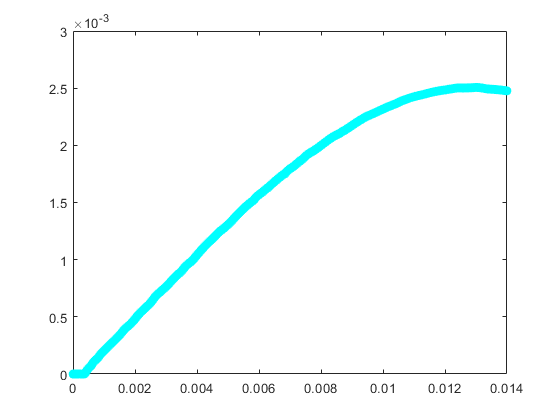

figure
load('D:\FOLDER\桌面\校数模\2017B\L-I-20C.mat')
I = I./1000;
P = P./1000;
plot(I, P, 'oc')
hold on


load('D:\FOLDER\桌面\校数模\2017B\Ti.mat')
lambda = 0.327974911948322;
a_0 = 0.00245295354589810;
a_1 = -2.24461489568760E-05;
a_2 = 8.55495131262933E-08;
a_3 = -3.04196846538548E-10;
a_4 = 6.38679397411974E-13;
Ith0 = 2.09792442194657E-05;
Rth = 3593.49598351965;
T = Ti(:,2);
It = Ti(:, 1);
Ioff = a_0 + a_1.*T + a_2.*T.^2 + a_3.*T.^3 + a_4.*T.^4;
Pi = lambda.*(It - Ith0 - Ioff);
Pi(Pi<0) = 0

Pi =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


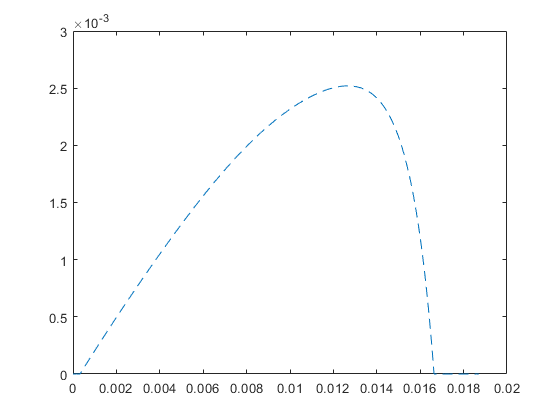

plot(It, Pi, '--')

% clear all
global i;
load('D:\FOLDER\桌面\校数模\2017B\L-I-20C.mat')
I = I/1000;

Ti = [];
k = 0;
for i = 0:1e-4:0.02
    k = k+1;
    Ti(k, 1:2) = [i fzero(@fitness_7, 350)];
end

正在退出 fzero: 将终止搜索包含符号变化的区间
 因为在搜索期间遇到 NaN 或 Inf 函数值。
(-1.43285e+77 处的函数值为 Inf。)
请检查函数或使用其他起始值重试。
正在退出 fzero: 将终止搜索包含符号变化的区间
 因为在搜索期间遇到 NaN 或 Inf 函数值。
(-1.43285e+77 处的函数值为 Inf。)
请检查函数或使用其他起始值重试。
正在退出 fzero: 将终止搜索包含符号变化的区间
 因为在搜索期间遇到 NaN 或 Inf 函数值。
(-1.43285e+77 处的函数值为 Inf。)
请检查函数或使用其他起始值重试。
正在退出 fzero: 将终止搜索包含符号变化的区间
 因为在搜索期间遇到 NaN 或 Inf 函数值。
(-1.43285e+77 处的函数值为 Inf。)
请检查函数或使用其他起始值重试。
正在退出 fzero: 将终止搜索包含符号变化的区间
 因为在搜索期间遇到 NaN 或 Inf 函数值。
(-1.43285e+77 处的函数值为 Inf。)
请检查函数或使用其他起始值重试。
正在退出 fzero: 将终止搜索包含符号变化的区间
 因为在搜索期间遇到 NaN 或 Inf 函数值。
(-1.43285e+77 处的函数值为 Inf。)
请检查函数或使用其他起始值重试。
正在退出 fzero: 将终止搜索包含符号变化的区间
 因为在搜索期间遇到 NaN 或 Inf 函数值。
(-1.43285e+77 处的函数值为 Inf。)
请检查函数或使用其他起始值重试。
正在退出 fzero: 将终止搜索包含符号变化的区间
 因为在搜索期间遇到 NaN 或 Inf 函数值。
(-1.43285e+77 处的函数值为 Inf。)
请检查函数或使用其他起始值重试。
正在退出 fzero: 将终止搜索包含符号变化的区间
 因为在搜索期间遇到 NaN 或 Inf 函数值。
(-1.43285e+77 处的函数值为 Inf。)
请检查函数或使用其他起始值重试。
正在退出 fzero: 将终止搜索包含符号变化的区间
 因为在搜索期间遇到 NaN 或 Inf 函数值。
(-1.43285e+77 处的函数值为 Inf。)
请检查函数或使用其他起始值重试。
正在退出 fzero: 将终止搜索包含符号变化的区间
 因为


Ti(isnan(Ti(:,2)), 2) = max(Ti(:, 2));
lambda = 0.327974911948322;
a_0 = 0.00245295354589810;
a_1 = -2.24461489568760E-05;
a_2 = 8.55495131262933E-08;
a_3 = -3.04196846538548E-10;
a_4 = 6.38679397411974E-13;
Ith0 = 2.09792442194657E-05;
Rth = 3593.49598351965;
T = Ti(:,2);
It = Ti(:, 1);
Ioff = a_0 + a_1.*T + a_2.*T.^2 + a_3.*T.^3 + a_4.*T.^4;
Pi = lambda.*(It - Ith0 - Ioff);
Pi(Pi<0) = 0

Pi = 	1.0e+-3 *

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0


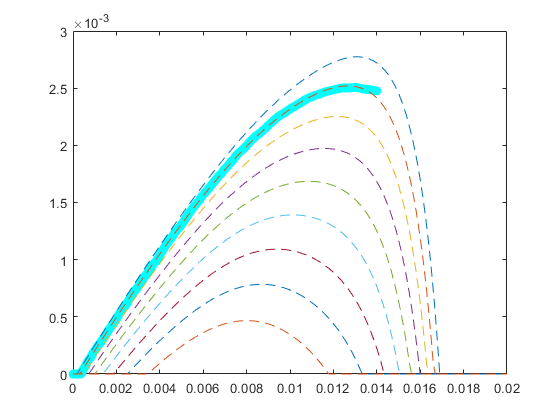

plot(It, Pi, '--')

% fzero(@fitness_7, 350)

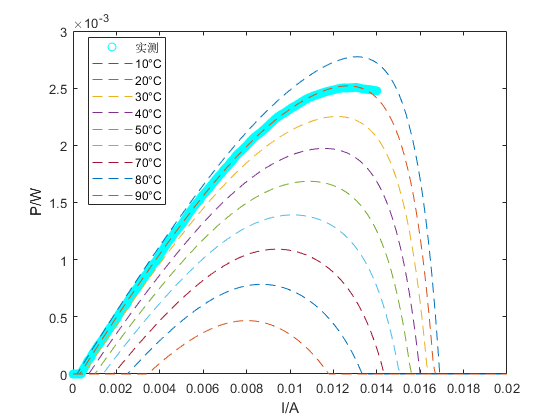

legend({'实测','10°C', '20°C', '30°C', '40°C', '50°C', '60°C', '70°C', '80°C', '90°C'}, 'Location','best')
xlabel('I/A')
ylabel('P/W')

function y = fitness_7(t)
load('D:\FOLDER\桌面\校数模\2017B\L-I-20C.mat')
load('D:\FOLDER\桌面\校数模\2017B\b.mat')
global i;
Tchange = 90;
lambda = 0.327974911948322;
Ith0 = 2.09792442194657E-05;
Rth = 3593.49598351965;
a_0 = 0.00245295354589810;
a_1 = -2.24461489568760E-05;
a_2 = 8.55495131262933E-08;
a_3 = -3.04196846538548E-10;
a_4 = 6.38679397411974E-13;
% i = 0.012;
% t = 380.276;
ui = b(1) + b(2).*i + b(3).*i.^2 + b(4).*i.^3 + b(5).*i.^4 + b(6).*i.^5;
y = lambda.*Rth.*a_4.*t.^4 + lambda.*Rth.*a_3.*t.^3 + lambda.*Rth.*a_2.*t.^2 + (lambda.*Rth.*a_1 - 1).*t + 273.15 + Tchange + Rth.*(lambda.*(Ith0 - i + a_0) + i.*ui);
% y = abs(y);
end
